# **1. INPUT CITRA**


I = imread('Abnormal/148495491-148495504-001.BMP');
%I = imread('Normal/153955676-153955746-001.BMP');
I = imresize(I, [200 NaN])

I = 200×499×3 uint8 array
I(:,:,1) =

   200   199   197   196   196   196   196   194   192   187   181   180   179   177   174   172   172   174   179   184   186   185   186   188   192   201   203   205   208   209   206   201   198   196   196   198   199   202   205   206   207   208   208   205   205   205   207   208   210   210   206   200   196   193   188   186   185   183   183   183   183   185   186   187   188   190   193   197   200   204   205   203   202   200   199   196   193   190   187   184   183   183   181   181   181   183   191   196   200   203   202   200   199   202   203   203   203   202   200   199   200   193   187   185   185   186   187   187   190   191   191   196   198   196   193   189   186   185   183   181   178   175   174   172   171   173   172   170   169   166   161   157   157   156   154   155   163   167   171   177   179   179   179   180   183   186   187   186   185   185   181   181   185   190   189   186   183   180   177   176  

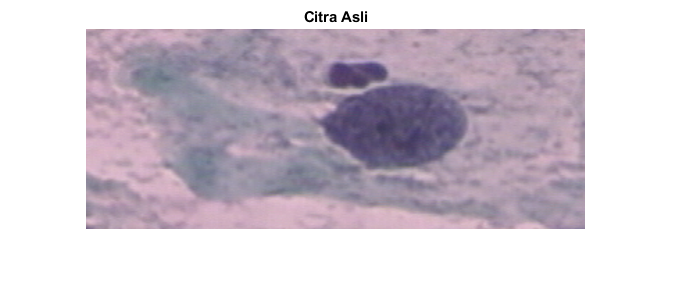

%I = imcrop(I,[15 15 200 175])
imshow(I), title('Citra Asli')

# **2. PERBAIKAN KONTRAS**

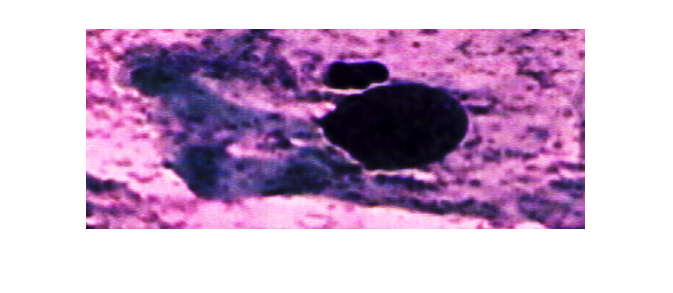

% %convert RGB ke LAB
% LAB = rgb2lab(I);
% 
% %skala fungsi adapthisteq
% L = LAB(:,:,1)/100;
% %CLAHE ke kanal L (contrast limited adaptive histogram equalization)
% L = adapthisteq(L,'NumTiles',[8 8],'ClipLimit',0.005);
% LAB(:,:,1) = L*100;
% %convert kembali citra lab ke rgb
% M = lab2rgb(LAB);
% figure, imshow (M), title('Contrast Enhanced')
M = histeq(I);
imshow(M)

# **3. GRAYSCALE**

% imhsv = rgb2hsv(M);
% S = imhsv(:,:,2)
% figure, imshow(S), title('HSV image');
% M = imopen(M,strel('disk',15));
gray = rgb2gray(M)

gray = 200×499 uint8 matrix
   185   183   179   174   174   174   174   177   171   150   126   119   117   111    97    92    89    95   111   127   131   124   130   137   152   183   195   202   209   209   204   195   183   171   166   178   178   184   196   199   201   204   204   194   185   187   201   206   206   206
   147   147   147   144   139   135   135   133   132   124   114   120   120   118   111   111   111   111   132   147   156   156   163   172   181   195   200   200   203   200   198   187   181   161   156   161   161   165   166   165   176   185   186   193   193   195   200   204   200   197
   112   108   106   103    98    98    98   104   105   105   106   116   118   117   120   129   134   139   159   174   181   184   195   202   204   202   202   200   195   187   185   179   166   157   150   150   148   148   148   144   151   158   164   181   192   200   200   200   192   183
   102    95    81    66    66    78    88   103   106   106   106   

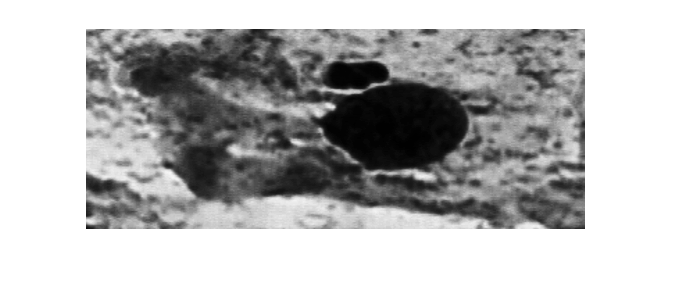

imshow(gray)

# **4. DETEKSI TEPI CANNY**

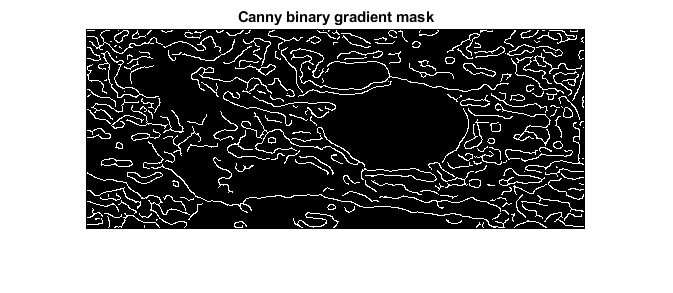

DI = imadjust(gray, [], [0 1]);
BWs = edge(DI, 'canny', (graythresh(DI) * 0.5));
figure, imshow(BWs), title('Canny binary gradient mask')

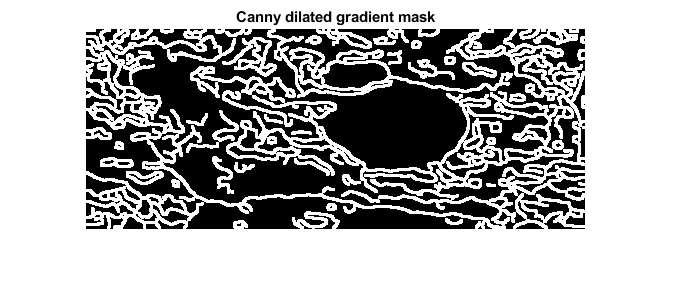

se90 = strel('line', 3, 90);
se0 = strel('line', 3, 0);
BWsdil = imdilate(BWs, [se90 se0]);
figure, imshow(BWsdil), title('Canny dilated gradient mask')

# **5. MENGISI LUBANG OBJEK**

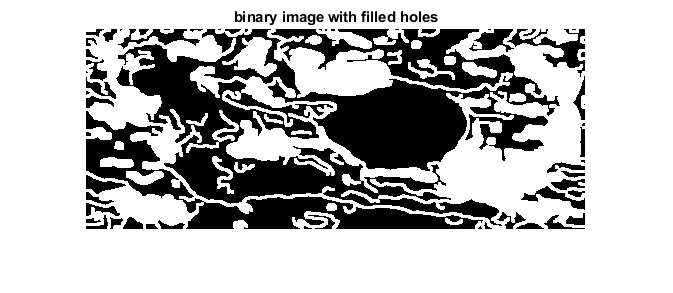

BWdfill = imfill(BWsdil, 'holes'); 
figure, imshow(BWdfill); title('binary image with filled holes');

% seD = strel('diamond',1);
% BWfinal = imerode(BWdfill,seD);
% BWfinal = imerode(BWfinal,seD); 
% figure, imshow(BWfinal), title('erosi');

# **MENGHILANGKAN NOISE**

**CLEAR BORDER**

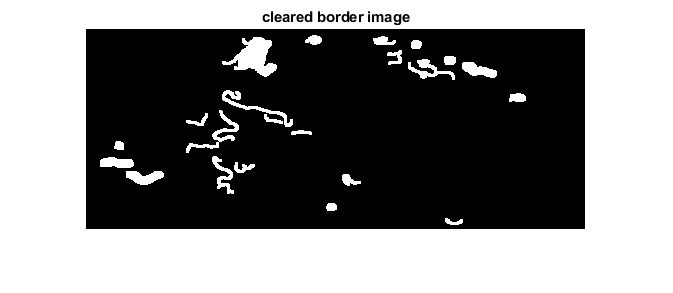

BWnobord = imclearborder(BWdfill, 4); 
figure, imshow(BWnobord), title('cleared border image');

**EROSI**

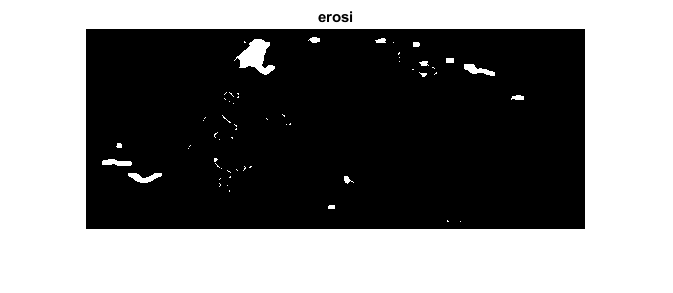

seD = strel('diamond',1);
BWfinal = imerode(BWnobord,seD);
BWfinal = imerode(BWfinal,seD); 
figure, imshow(BWfinal), title('erosi');

**REMOVE SMALL OBJECT**

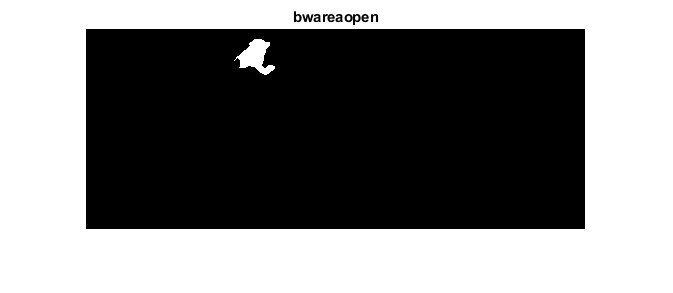

BWfix = bwareaopen(BWfinal, 200);
imshow(BWfix), title('bwareaopen')

# **REGIONPROPS**

S = regionprops(BWfix, 'Centroid', 'BoundingBox', 'Area'); 
size(S) %menampilkan ukuran larik dari S

ans =      1     1


S %menampilkan struktur S

S = struct with fields:
           Area: 724
       Centroid: [170.2693 28.1630]
    BoundingBox: [148.5000 10.5000 41 36]


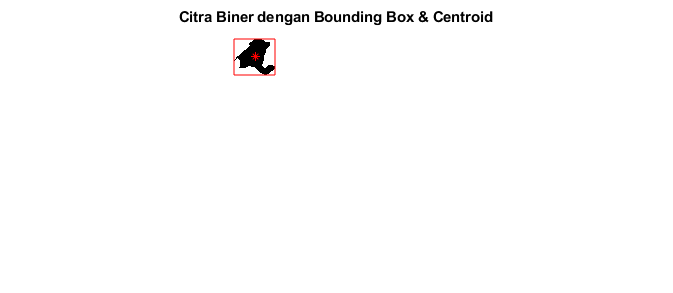

ans =     'Banyaknya Pixel objek ke 1 = 724 _dengan centroid[1.702693e+02 2.816298e+01]
     '



figure;imshow(~BWfix), title('Citra Biner dengan Bounding Box & Centroid'); %menampilkan citra biner
hold on ; %tetap mengaktifan figur citra biner di atas

%----------------------------------------------- 
%untuk Menggambar kotak terkecil yang melingkupi Objek
%dengan fungsi rectangle warna garis dengan kotak merah (red)
for i=1:size(S,1)
    rectangle('Position', S(i).BoundingBox,'edgecolor','red');
    
    %Menggambar posisi centroid setiap objek
    plot(S(i).Centroid(1),S(i).Centroid(2),'r*');
    
    %Mencetak banyaknya pixel dan posisi centroid setiap objek
    sprintf('Banyaknya Pixel objek ke %d = %d _dengan centroid[%d %d]\n',i, S(i).Area,..._
    S(i).Centroid(1), S(i).Centroid(2))

end

# **LABELING**

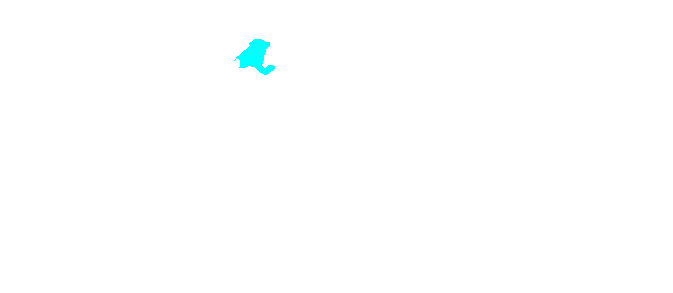

CC = bwconncomp(BWfix);

%memberi label berbeda pada setiap objek
L = labelmatrix(CC);
 
%setiap objek akan diberi warna RGB
IL = label2rgb(L);
 
%menampilkan gambar setelah digabung
%figure;imshow(BWfix);
%menampilkan gambar berwarna RGB
 figure;imshow(IL);

# **OUTLINE ORIGINAL IMAGE**

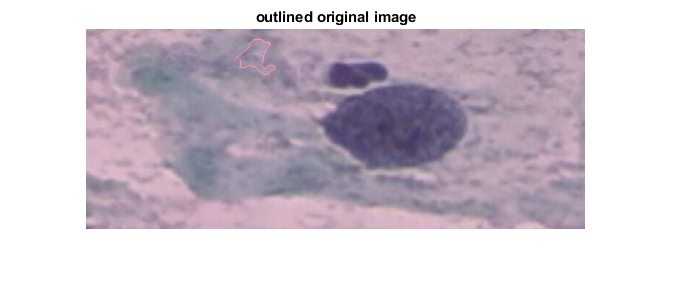

BWoutline = bwperim(BWfix); 
Segout = I; Segout(BWoutline) = 255; 
figure, imshow(Segout), title('outlined original image');